clear all;
close all;
[X,y]=data(100,1.5)

X =    -0.8418   -0.7416    0.6215   -0.4102    0.4789   -0.3604    0.3554   -0.3417    0.4921   -2.1743    0.1254    2.5002    0.4492   -2.8083   -2.4991   -2.9185   -0.7644    2.5040    2.2577    0.6424   -2.2424   -2.8088   -0.2895    2.5314    0.4520   -2.2415   -2.9863   -2.6045   -0.4800    2.4503    2.5451    2.5159    0.6909   -0.4907    2.8156    0.6492   -2.4631   -2.8263   -0.7180    0.5624   -0.8474    0.4923   -0.5408    2.4961    0.5549   -2.4482   -0.0951    0.4679   -0.4278    0.7791
   -0.7416    0.6215   -0.4102    0.4789   -0.3604    0.3554   -0.3417    0.4921   -2.1743    0.1254    2.5002    0.4492   -2.8083   -2.4991   -2.9185   -0.7644    2.5040    2.2577    0.6424   -2.2424   -2.8088   -0.2895    2.5314    0.4520   -2.2415   -2.9863   -2.6045   -0.4800    2.4503    2.5451    2.5159    0.6909   -0.4907    2.8156    0.6492   -2.4631   -2.8263   -0.7180    0.5624   -0.8474    0.4923   -0.5408    2.4961    0.5549   -2.4482   -0.0951    0.4679   -0.4278    0.7791   -2

y =      1    -1     1    -1     1    -1     1    -1    -1     1     1    -1    -1    -1    -1     1     1     1    -1    -1    -1     1     1    -1    -1    -1    -1     1     1     1     1    -1     1     1    -1    -1    -1     1    -1     1    -1     1     1    -1    -1     1    -1     1    -1    -1


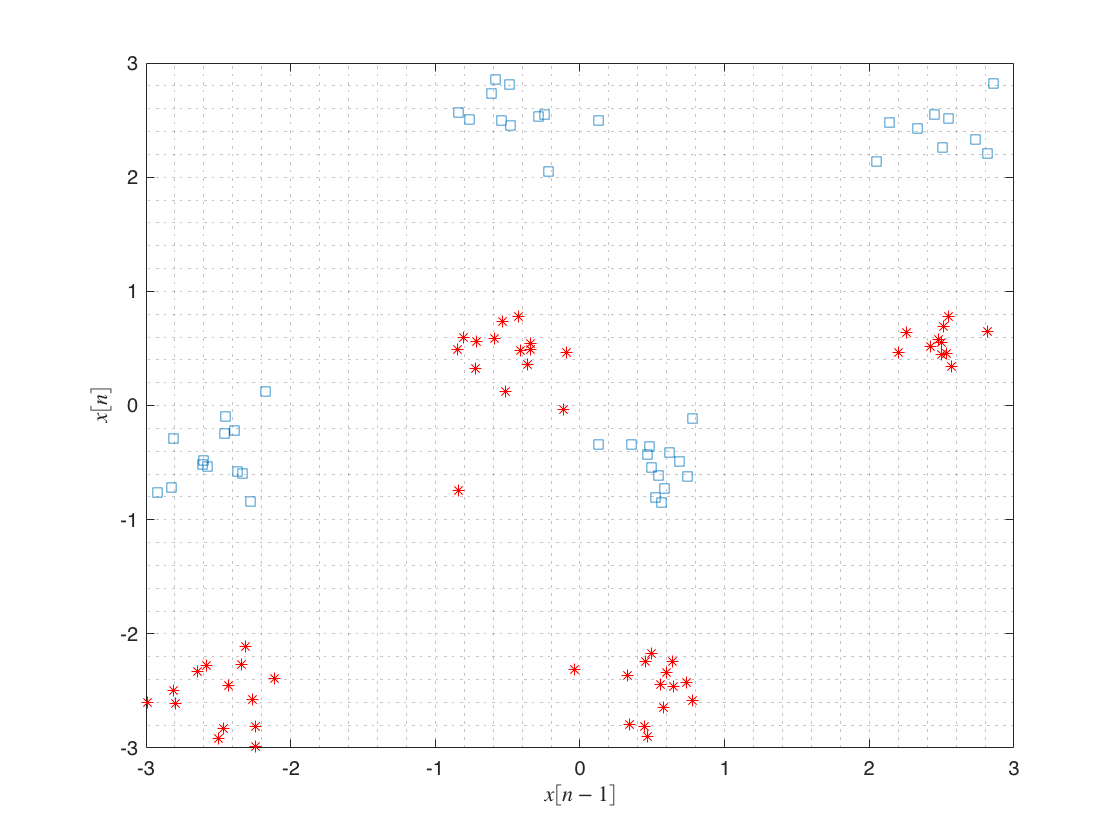


x_center = 0;
y_center = 0;
center = transpose(repmat([x_center; y_center], 1, length(X)));

theta = pi/2; % Rotate matrix 90° counter-clockwise
v = X(:,1:2);

R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
so = R*v';  % Rotate about the origin
vo = so';

X(:,1) = vo(:,1);
X(:,2) = vo(:,2);
   
i1=find(y==1);
i2=find(y==-1);

figure(1)
plot(X(1,i1),X(2,i1),'s')
hold on
plot(X(1,i2),X(2,i2),'r*')
grid minor
xlabel('$x[n-1]$','Interpreter','latex')
ylabel('$x[n]$','Interpreter','latex')

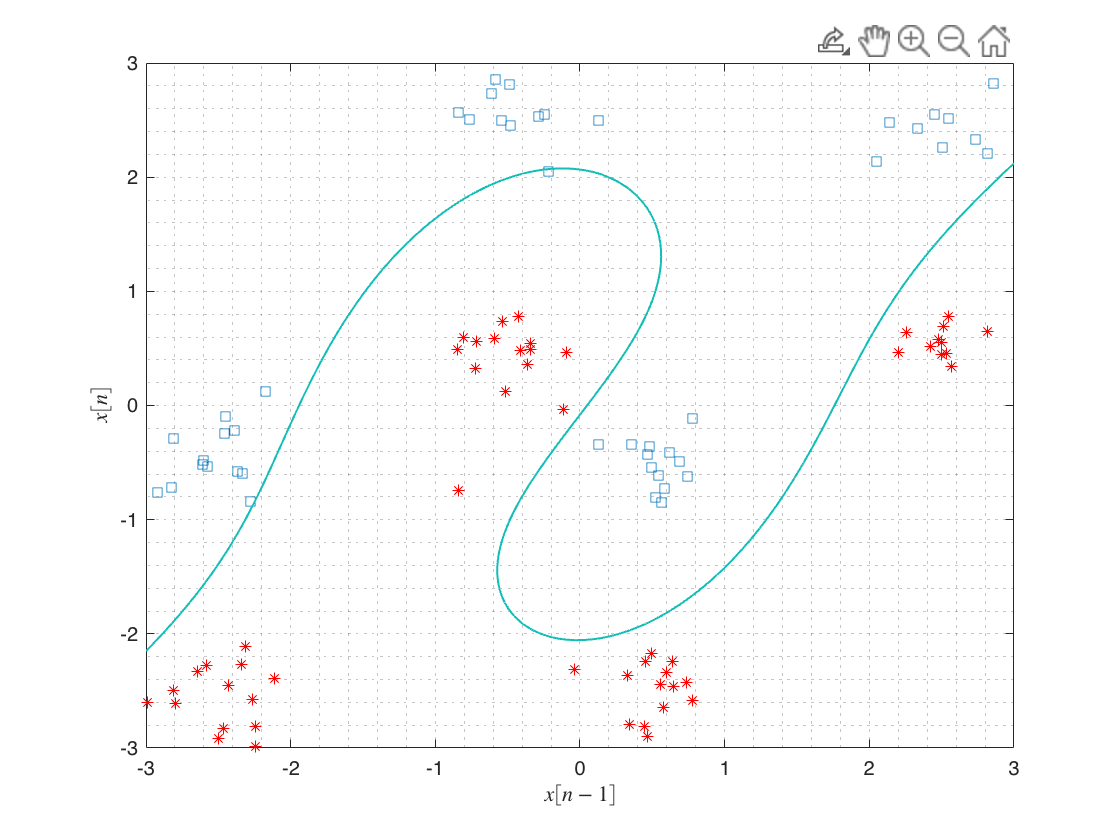

% Train the datasets
x_2 = X(1,:);
x_3 = X(2,:);

%     Gamma = 10;
%     K_1 = (X' * X + 1).^3;
%     Alpha = pinv(K_1' * K_1) * y';  % Dual representation and the polynomial kernel
%     y = Alpha' * K_1;

    Gamma = 10;
    K_1 = (X' * X + 1).^3;    % Dot products between data for test and training
    Alpha = pinv(K_1 + Gamma * eye(100)) * y';    % Using ridge regression
    y = Alpha' * K_1;

% % Non-Linear Transformation (3rd Order)
% Volterra_eqn_train = [ones(1,100);x_2;x_3;x_2.^2;x_3.^2;x_2.*x_3;(x_2.^2).*x_3;(x_3.^2).*x_2;x_2.^3;x_3.^3];
% pi = Volterra_eqn_train * Volterra_eqn_train';
% w = pinv(pi) * Volterra_eqn_train * y';
% y = w' * Volterra_eqn_train;

% Test the datasets
% Grid/Xn_2 and Xn_3 Vectors
    [G1,G2] = meshgrid(linspace(-3,3,100), linspace(-3,3,100));
% x_2 = Xn_2(:)';
% x_3 = Xn_3(:)';
    y_1 = G2(:)';
    x_2 = G1(:)';
    x_3 = [x_2' y_1']';
% % 3rd Order/Tranformation
% volterra_eqn_test = [ones(1,100.^2);x_2;x_3;x_2.^2;x_3.^2;x_2.*x_3;(x_2.^2).*x_3;(x_3.^2).*x_2;x_2.^3;x_3.^3];
% y_n = w' * volterra_eqn_test;

    % Dot products between data for test_sets 
    K_2 = (X' * x_3 + 1).^3;
    Y1 = Alpha' * K_2;

% Buffering Vector into Matrix
% b = buffer(y_n,size(Xn_2,1),0);

    R = reshape(Y1,size(G1));

% Contour Plot for Matrix
contour(G1,G2,R,[0 0], 'LineWidth',1)

function [X,y]=data(N,a)
N=N+1;
y=sign(randn(1,N));
x=filter([1 a],1,y)+0.2*randn(size(y));
X=buffer(x,2,1,'nodelay');  % Convolution
y=y(2:end);
end